# Generate DVB-S2 Waveform for Single-Input Stream

Generate a Digital Video Broadcasting Satellite Second Generation (DVB-S2) time-domain waveform for a single-input transport stream (TS) with a single physical layer (PL) frame per stream. Visualize the waveform using constellation plots and signal spectrum.

This example uses MAT-files with LDPC parity matrices. If the MAT-files are not available on the path, download and unzip the MAT-files by entering this code at the MATLAB command prompt.

if ~exist('dvbs2xLDPCParityMatrices.mat','file')
    if ~exist('s2xLDPCParityMatrices.zip','file')
        url = 'https://ssd.mathworks.com/supportfiles/spc/satcom/DVB/s2xLDPCParityMatrices.zip';
        websave('s2xLDPCParityMatrices.zip',url);
        unzip('s2xLDPCParityMatrices.zip');
    end
addpath('s2xLDPCParityMatrices');
end

Specify the number of PL frames per stream.

numFrames = 1;

Create a DVB-S2 System object. Specify the modulation scheme and FEC rate (MODCOD) and data field length (DFL).

 s2WaveGen = dvbs2WaveformGenerator_modified;
 s2WaveGen.MODCOD = 10;  % 16APSK 5/6
 s2WaveGen.StreamFormat = "GS";
 s2WaveGen.FECFrame = "normal";
 
 s2WaveGen.DFL = 57392;
 s2WaveGen.UPL = 0;
 s2WaveGen.RolloffFactor = 0.20;
 s2WaveGen.HasPilots = false; % Pilot insertion indication
 s2WaveGen.ISSYI = 0;

 s2WaveGen.HasPilots = 0;
s2WaveGen.FilterSpanInSymbols = 10

s2WaveGen =   dvbs2WaveformGenerator_modified with properties:

           StreamFormat: "GS"
        NumInputStreams: 1
                    UPL: 0
               FECFrame: "normal"
                 MODCOD: 10
                    DFL: 57392
              HasPilots: 0
          RolloffFactor: 0.2000
    FilterSpanInSymbols: 10
       SamplesPerSymbol: 4


 %s2WaveGen.ISCRFormat = "long"
 disp(s2WaveGen)

  dvbs2WaveformGenerator_modified with properties:

           StreamFormat: "GS"
        NumInputStreams: 1
                    UPL: 0
               FECFrame: "normal"
                 MODCOD: 10
                    DFL: 57392
              HasPilots: 0
          RolloffFactor: 0.2000
    FilterSpanInSymbols: 10
       SamplesPerSymbol: 4



 % Read binary data from a text file
filename = '/MATLAB Drive/DVBS2_script/s2_inputfiles/normal_c8_9_input.txt';
fileID = fopen(filename, 'r');
if fileID == -1
    error('Error opening the binary data file.');
end
binaryData = fscanf(fileID, '%1d');
fclose(fileID);


Create a bit vector of information bits, `data`, of concatenated TS user packets.

if strcmpi(s2WaveGen.StreamFormat, "TS")
syncBits = [0 1 0 0 0 1 1 1]';    % Sync byte for TS packet is 47 Hex
pktLen = s2WaveGen.UPL;          % UP length without sync bits
numPkts = s2WaveGen.MinNumPackets * numFrames;
%txRawPkts = randi([0 1],pktLen,numPkts);
requiredLength = (pktLen + length(syncBits)) * numPkts;
% if length(binaryData) < requiredLength
%     error('Insufficient data in the input file. Expected at least %d bits.', requiredLength);
% end
% 
% % Reshape the binary data into TS packets
% binaryData = binaryData(1:min(end, requiredLength - numPkts * length(syncBits))); 
binaryData = binaryData(1:min(end, requiredLength - numPkts * length(syncBits))); 

% Ensure binaryData has the correct length
if length(binaryData) < (pktLen * numPkts)
    error('Insufficient data in the input file. Expected at least %d bits.', pktLen * numPkts);
end
txRawPkts = reshape(binaryData, pktLen, numPkts); % Data without sync bits

% Prepend the sync byte to each packet
txPkts = [repmat(syncBits, 1, numPkts); txRawPkts];

% Flatten into a single vector
data = txPkts(:);

else
    % GS format: Continuous bitstream
    requiredLength = s2WaveGen.DFL * numFrames;  % Required bits = DFL * numFrames

    if length(binaryData) < requiredLength
        error('Insufficient data in the input file. Expected at least %d bits.', requiredLength);
    end

 % Trim the binary data to the required length
    binaryData = binaryData(1:requiredLength);
    data = binaryData(:);  % Convert to column vector
end
% txPkts = [repmat(syncBits,1,numPkts); txRawPkts];
% data = txPkts(:);1`

Generate a DVB-S2 time-domain waveform using the information bits, `data`.

txWaveform = s2WaveGen(data);

Data saved in /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/s2_bbscrambler_output.hex
Data saved in: /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/s2_bbscrambler_output.hex
Data saved in /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/s2_bbscrambler_output.txt
Data saved in: /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/s2_bbscrambler_output.txt
Data saved in /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/bch_output.hex
Data saved in: /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/bch_output.hex
Data saved in /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/bch_output.txt
Data saved in: /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_script_data/normal_qpsk_c8_9_gs/bch_output.txt
Data saved in /MATLAB Drive/DVBS2_script/data_comparision/dvbs2_

Visualize the constellation plot for the generated DVB-S2 time-domain waveform by creating a constellation diagram System object.

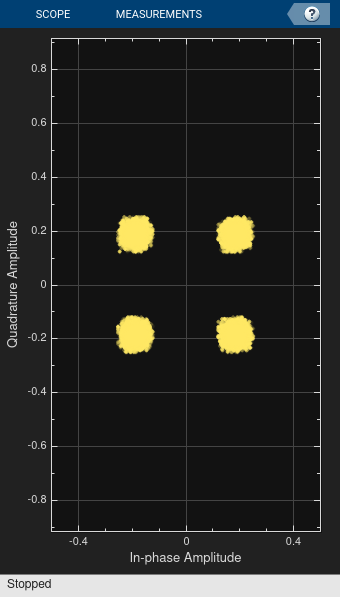

sps = s2WaveGen.SamplesPerSymbol;
constel = comm.ConstellationDiagram('ColorFading',true, ...
    'ShowTrajectory',0, ...
    'SamplesPerSymbol',sps, ...
    'ShowReferenceConstellation',false, ...
    'XLimits',[-0.5 0.5], 'YLimits',[-0.5 0.5]);
plHeaderLen = 90*sps;           % PL header length
constel(txWaveform(plHeaderLen+1:end));
release(constel);

Display the frequency spectrum of the generated DVB-S2 time-domain waveform by creating a spectrum analyzer System object. 

BW = 36e6;                 % Typical satellite channel bandwidth
Fsym = BW/(1+s2WaveGen.RolloffFactor);
Fsamp = Fsym*sps;
scope = spectrumAnalyzer('SampleRate',Fsamp);
scope(txWaveform)

*Copyright 2020 The MathWorks, Inc.*